t = 0:0.01:4;
k = 0;
for i = 1:21;
a(i) = 6.2-i*0.2;
for j = 1:21;
b(j) = 6.2-j*0.2;
for h = 1:31;
c(h) = 12.2-h*0.2;
num = [0 2*a(i)+c(h) a(i)^2+b(j)^2+2*a(i)*c(h) (a(i)^2+b(j)^2)*c(h)];
den = [1 2*a(i)+c(h) a(i)^2+b(j)^2+2*a(i)*c(h) (a(i)^2+b(j)^2)*c(h)];
y = step(num,den,t);
m = max(y);
s = 401; 

while y(s) > 0.98 & y(s) < 1.02;
s = s-1; 
end;

ts = (s-1)*0.01;
if m < 1.19 & m > 1.02 & ts < 1.0;
k = k+1;
table(k,:) = [a(i) b(j) c(h) m ts];

end
end
end
end

table(k,:) = [a(i) b(j) c(h) m ts]

table =     4.2000    2.0000   12.0000    1.1896    0.8500
    4.0000    2.0000   12.0000    1.1881    0.8700
    4.0000    2.0000   11.8000    1.1890    0.8900
    4.0000    2.0000   11.6000    1.1899    0.9000
    3.8000    2.2000   12.0000    1.1883    0.9300
    3.8000    2.2000   11.8000    1.1894    0.9400
    3.8000    2.0000   12.0000    1.1861    0.8900
    3.8000    2.0000   11.8000    1.1872    0.9100
    3.8000    2.0000   11.6000    1.1882    0.9300
    3.8000    2.0000   11.4000    1.1892    0.9400


num_p1 = [0.755];
den_p1 = [1 13.87 34.91];
tf_p1 = tf( num_p1, den_p1)

tf_p1 =
 
          0.755
  ---------------------
  s^2 + 13.87 s + 34.91
 
Continuous-time transfer function.
Model Properties



syms k
expression = (k + 12 + 2*sqrt(-1))*(k + 12 - 2*sqrt(-1))*(k + 12)

$$expression = \left(k+12\right)\,\left(k+12-2\,\mathrm{i}\right)\,\left(k+12+2\,\mathrm{i}\right)$$

expanded_expression = expand(expression);
decimal_expression = vpa(expanded_expression)

$$decimal\_expression = k^{3}+36.0\,k^{2}+436.0\,k+1776.0$$

k =8.71;
a_plus_b = 13.31;
a_and_b = 39.488;

num_gc = [k k*a_plus_b k*a_and_b];
den_gc = [1 0];
tf_gc = tf( num_gc, den_gc)

tf_gc =
 
  8.71 s^2 + 115.9 s + 343.9
  --------------------------
              s
 
Continuous-time transfer function.
Model Properties


num_gc1 = [27.113 162.138 343.9];
den_gc1 = [1 0];
tf_gc1 = tf( num_gc1, den_gc1)

tf_gc1 =
 
  27.11 s^2 + 162.1 s + 343.9
  ---------------------------
               s
 
Continuous-time transfer function.
Model Properties


sample_time = 0.01;
tf_d = c2d( tf_gc1, sample_time, 'tustin')

tf_d =
 
  5586 z^2 - 1.084e04 z + 5262
  ----------------------------
            z^2 - 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


num_gc2 = [-18.403 -46.238];
den_gc2 = [1];
tf_gc2 = tf( num_gc2, den_gc2)

tf_gc2 =
 
  -18.4 s - 46.24
 
Continuous-time transfer function.
Model Properties


sample_time = 0.01;
tf_d = c2d( tf_gc2, sample_time, 'tustin')

tf_d =
 
  -3727 z + 3634
  --------------
      z + 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.
Model Properties


tf_g1_sh1 = feedback( tf_p1, tf_gc2);
tf_g1_serias = series( tf_gc1, tf_g1_sh1);
tf_final = feedback( tf_g1_serias, 1)

tf_final =
 
     20.47 s^2 + 122.4 s + 259.6
  ---------------------------------
  s^3 + 20.45 s^2 + 122.4 s + 259.6
 
Continuous-time transfer function.
Model Properties


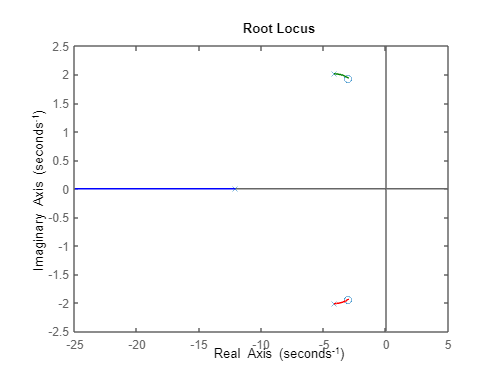

rlocus(tf_final)

pole(tf_g1_serias)

ans =    0.0000 + 0.0000i
   0.0121 + 0.0128i
   0.0121 - 0.0128i
